% 1. create the simulation name and the folder to save all simulated
% samples and parameters

% give this simulation a name
SimulationName='Simulation_NoiseSource_20240105';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/';
% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/Simulation_NoiseSource_20240105/'

cd(filepath)

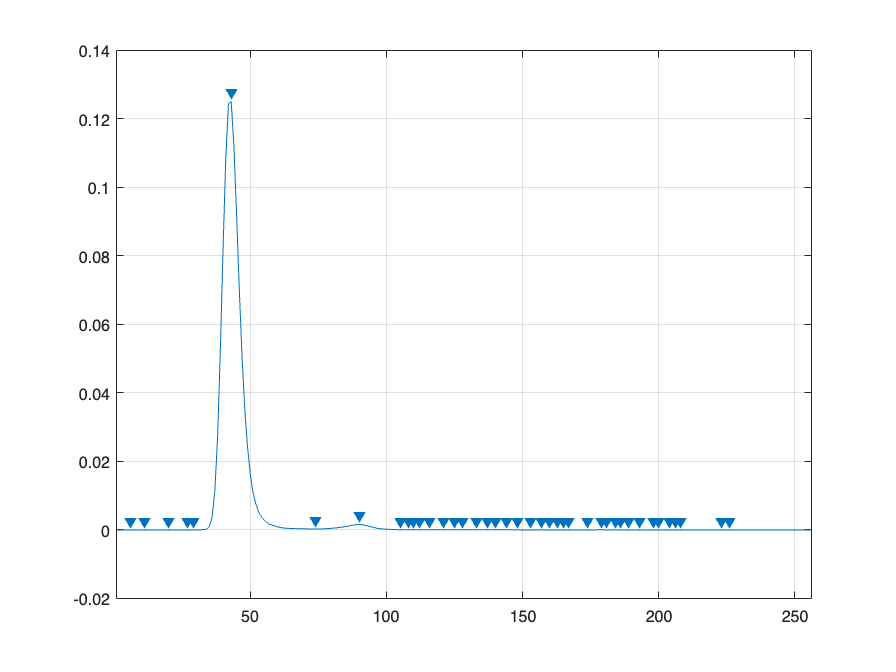

% 2. load prf, calculate the full width half maximum of the prf; use the FWHM to
% generate a corresponding gaussian PRF for PMT simulation

PrfName_original = 'prf_InsightBottomGreen_20231017.mat';

load(PrfName_original)
figure
findpeaks(prf)

[pks, locs, width, p] = findpeaks(prf); % Derive the peak location and the FWHM of the PRF curve
width(6)*(12.5/256) % The main peak of the PRF is the 6th peak. This is the FWHM of experimental collected PRF

ans = 0.3423

gaussian_sigma = (width(6)*(12.5/256))/2.355 % for normal distribution, FWHM = 2*sqrt(2*ln2)*sigma = 2.355*sigma; so sigma = FWHM/2.355

gaussian_sigma = 0.1453

gaussian_miu = locs(6) * (12.5/256) % Guassian distributio mean same as the peak location

gaussian_miu = 2.0996


gaussian_x = (1:1:256)*(12.5/256); % Create x axis
gaussian_y = 1/(gaussian_sigma*sqrt(2*pi))*exp(-(gaussian_x-gaussian_miu).^2/(2*gaussian_sigma^2)); % Calculate y axis of the Gaussian distribution
gaussian_y = gaussian_y/sum(gaussian_y); % Normalize the Gaussian distribution with sum being 1

% Plot the experimental PRF and the Gaussian PRF to compare
% figure
% plot(gaussian_x, gaussian_y)
% hold on
% plot(gaussian_x, prf)
% legend('gaussian', 'collected')
% hold off

% Save the PRF file under a name
prf = gaussian_y;
PrfName_PMT = 'Prf_gaussion_PMT.mat';
% save(PrfName_PMT, 'prf')
PRF_PMT = prf;
PRF_PMT_norm = PRF_PMT/max(PRF_PMT);


% 3. create a Gaussian PRF  hybrid detector (HBD) prf
HBD_width = 120/1000 % 120 ps accroding to BH website https://www.becker-hickl.com/products/hybrid-photo-detectors/

HBD_width = 0.1200

HBD_sigma = (HBD_width)/2.355 % for normal distribution, FWHM = 2*sqrt(2*ln2)*sigma = 2.355*sigma; so sigma = FWHM/2.355

HBD_sigma = 0.0510

HBD_miu = locs(6) * (12.5/256) % Guassian distributio mean same as the peak location

HBD_miu = 2.0996

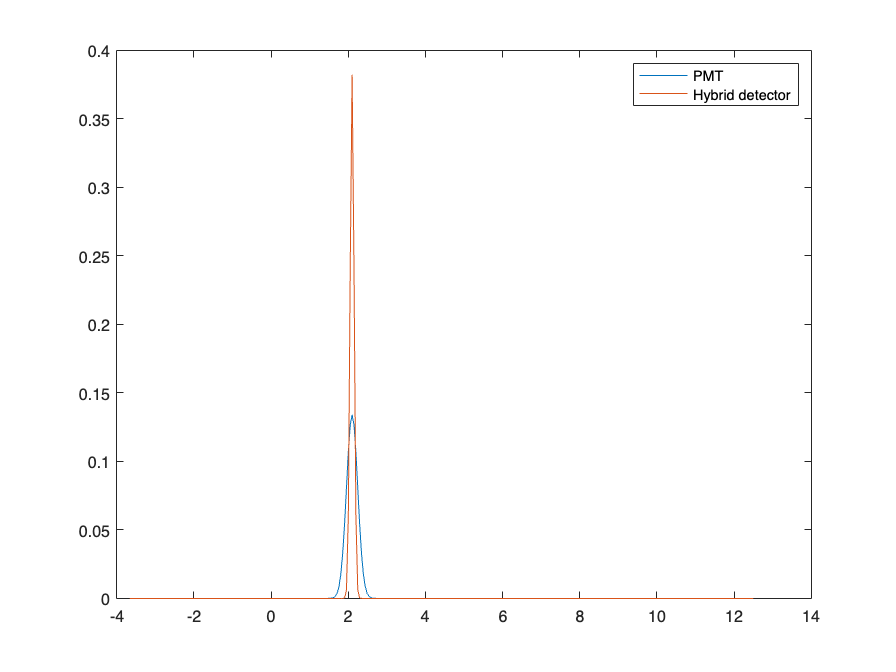


HBD_x = (1:1:256)*(12.5/256); % Create x axis
HBD_y = 1/(HBD_sigma*sqrt(2*pi))*exp(-(HBD_x-HBD_miu).^2/(2*HBD_sigma^2));  % Calculate y axis of the Gaussian distribution
HBD_y = HBD_y/sum(HBD_y); % Guassian distributio mean same as the peak location

% plot the PRF for PMT and HBD together to compare
figure
plot(gaussian_x, gaussian_y)
hold on
plot(gaussian_x, HBD_y)
legend('PMT', 'Hybrid detector')
hold off


% save the PRF under a file
prf = HBD_y

prf =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0061    0.0609    0.2415    0.3823    0.2415    0.0609    0.0061    0.0002    0.0000    0.0000    0.0000


PrfName_HBD = 'Prf_gaussion_HBD.mat';
% save(PrfName_HBD, 'prf')
PRF_HBD = prf;
PRF_HBD_norm = PRF_HBD/max(PRF_HBD);

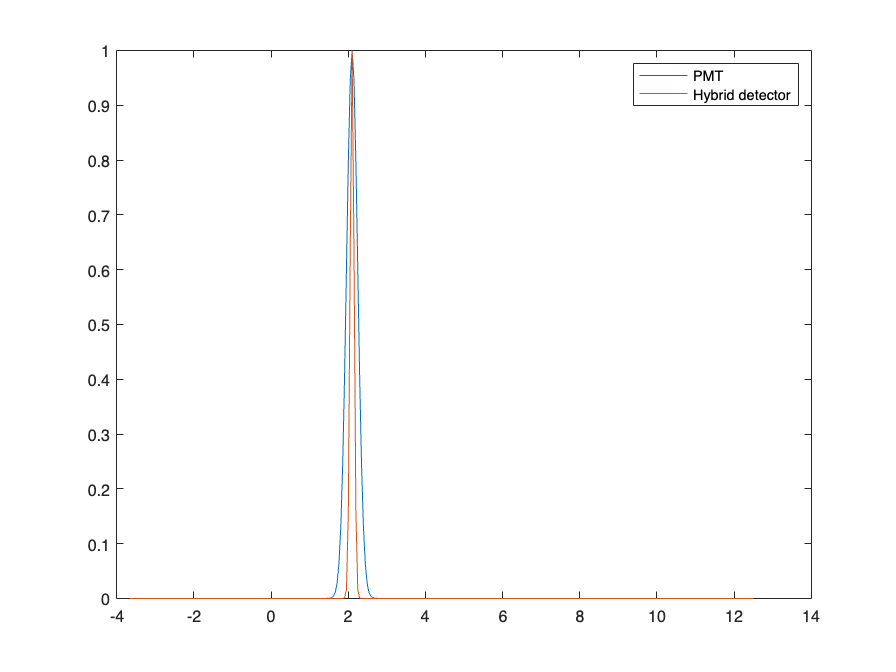

figure
plot(gaussian_x, PRF_PMT_norm)
hold on
plot(gaussian_x, PRF_HBD_norm)
legend('PMT', 'Hybrid detector')
hold off

TP = 1000000;
p1 = 0.5;
p2 = 1 - p1;
tau1 = 2.14;
tau2 = 0.69;

PopulationName = 'TestNoiseSource_Population_20240105.mat';

% GenPop512_FLIM_v2(TP, p1, p2, tau1, tau2, PopulationName)

load(PopulationName); 



n1_HBD = conv(counts, PRF_HBD);
n_HBD = n1_HBD(1:256) + n1_HBD(257:512);


n1_PMT = conv(counts, PRF_PMT);
n_PMT = n1_PMT(1:256) + n1_PMT(257:512);

fitting_range = [1 256];
Emp_anlytical_HBD = CalcEmpLft(fitting_range, n_HBD)

Emp_anlytical_HBD = 3.7840

Emp_anlytical_PMT = CalcEmpLft(fitting_range, n_PMT)

Emp_anlytical_PMT = 3.7839

% load Population and simulate 500 sample without convolution
SS = 500000;
load(PopulationName); 
n_sample_all = zeros(500, 512);
Sample_all = {};
xsim = (0:1:511)*(12.5/256);

for i = 1:500

    Sample=Population(randi(length(Population), 1, SS));
    Sample_all{i} = Sample;
    [n_sample, xout1]=hist(Sample, xsim);
    n_sample_all(i, :) = n_sample;

end

% analytical convolution of simulated samples using different PRF
n_sample_conv_all_PMT = zeros(500, 256);
n_sample_conv_all_HBD = zeros(500, 256);

load(PrfName_PMT);
for i = 1:500
    n_sample = n_sample_all(i,:);
    n_sample_conv = conv(n_sample, prf);
    n_sample_conv = n_sample_conv(1:256) + n_sample_conv(257:512);
    n_sample_conv_all_PMT(i, :) = n_sample_conv;
end

load(PrfName_HBD);
for i = 1:500
    n_sample = n_sample_all(i,:);
    n_sample_conv = conv(n_sample, prf);
    n_sample_conv = n_sample_conv(1:256) + n_sample_conv(257:512);
    n_sample_conv_all_HBD(i, :) = n_sample_conv;
end

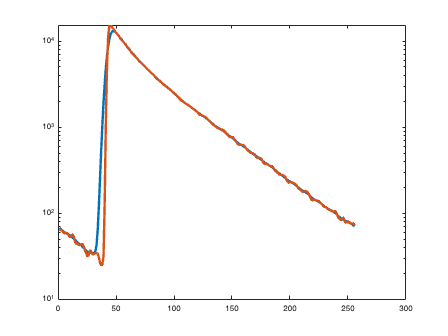

figure
semilogy(n_sample_conv_all_PMT(1,:), 'LineWidth', 3)
hold on
semilogy(n_sample_conv_all_HBD(1,:), 'LineWidth', 3)

fitting_range = [10 235];

sample_Emplft_PMT = zeros(500, 1);
sample_Emplft_HBD = zeros(500, 1);

for i = 1:500

    n_sensor = n_sample_conv_all_PMT(i, :);
    sample_Emplft_PMT(i) = CalcEmpLft(fitting_range, n_sensor);

    n_sensor = n_sample_conv_all_HBD(i, :);
    sample_Emplft_HBD(i) = CalcEmpLft(fitting_range, n_sensor);

end

ch = 1; % only for FLIM channel 1
spc.datainfo.psPerUnit = (12.5/256)*1000;
spc.fits{1}.beta2 = 2.14; % p1 and p2 as 0.5
spc.fits{1}.beta4 = 0.69;

sample_num = 500; 

n_all = {};

load(PrfName_PMT)
spc.fits{1}.prf = prf;
n_all{1} = n_sample_conv_all_PMT;

[p1_fitted_sample_PMT, tau_empTrunc_single_sample_PMT, fitting_parameters_sample_PMT] = RunFitting(sample_num, n_all);

load(PrfName_HBD)
spc.fits{1}.prf = prf;
n_all{1} = n_sample_conv_all_HBD;

[p1_fitted_sample_HBD, tau_empTrunc_single_sample_HBD, fitting_parameters_sample_HBD] = RunFitting(sample_num, n_all);

% Just use one simulated sample and do convolution for 500 times
% the number 425 one is close to the mean

Sample = Sample_all{425};

load(PrfName_PMT); % Load from PRF
xsim2=(0:1:767)*(12.5/256);
n_conv_all_PMT_p1 = zeros(500, 256);

for i_sim = 1:500

    SampleC=zeros(1, length(Sample));
    for i=1:length(Sample)
        b=rand();
        a=find(histc(b,[0;cumsum(prf(:))]))-1;
        SampleC(i)=Sample(i)+a*(12.5/256); % Randomly draw a distribution based on the probability specified in the prf.
    
    end
    
    [n2, xout2]=hist(SampleC, xsim2);
    n3=n2(257:512);
    n_conv = n2(1:256)+n3;
    n_conv_all_PMT_p1(i_sim, :) = n_conv;

end


% do convolution 500 times use PrfName2 = 'Prf_gaussion_HBD_500.mat';

load(PrfName_HBD); % Load from PRF
n_conv_all_HBD_p1 = zeros(500, 256);

for i_sim = 1:500

    SampleC=zeros(1, length(Sample));
    for i=1:length(Sample)
        b=rand();
        a=find(histc(b,[0;cumsum(prf(:))]))-1;
        SampleC(i)=Sample(i)+a*(12.5/256); % Randomly draw a distribution based on the probability specified in the prf.
    
    end
    
    [n2, xout2]=hist(SampleC, xsim2);
    n3=n2(257:512);
    n_conv = n2(1:256)+n3;
    n_conv_all_HBD_p1(i_sim, :) = n_conv;

end

fitting_range = [1 256];

conv_Emplft_PMT = zeros(500, 1);
conv_Emplft_HBD = zeros(500, 1);

for i = 1:500

    n_sensor = n_conv_all_PMT(i, :);
    conv_Emplft_PMT(i) = CalcEmpLft(fitting_range, n_sensor);

    n_sensor = n_conv_all_HBD(i, :);
    conv_Emplft_HBD(i) = CalcEmpLft(fitting_range, n_sensor);

end

mean(conv_Emplft_HBD)
mean(conv_Emplft_PMT)
[h, p] = ttest2(conv_Emplft_HBD, conv_Emplft_PMT, 'Vartype','unequal')

h = 1

p = 2.1953e-19

ch = 1; % only for FLIM channel 1
spc.datainfo.psPerUnit = (12.5/256)*1000;
spc.fits{1}.beta2 = 2.14; % p1 and p2 as 0.5
spc.fits{1}.beta4 = 0.69;

sample_num = 500; 

n_all = {};

load(PrfName_PMT)
spc.fits{1}.prf = prf;
n_all{1} = n_conv_all_PMT;

[p1_fitted_sample_PMT, tau_empTrunc_single_sample_PMT, fitting_parameters_sample_PMT] = RunFitting(sample_num, n_all);

load(PrfName_HBD)
spc.fits{1}.prf = prf;
n_all{1} = n_conv_all_HBD;

[p1_fitted_sample_HBD, tau_empTrunc_single_sample_HBD, fitting_parameters_sample_HBD] = RunFitting(sample_num, n_all);

ch = 1; % only for FLIM channel 1
spc.datainfo.psPerUnit = (12.5/256)*1000;
spc.fits{1}.beta2 = 2.14; % p1 and p2 as 0.5
spc.fits{1}.beta4 = 0.69;

sample_num = 500; 

n_all = {};

load(PrfName_PMT)
spc.fits{1}.prf = prf;
n_all{1} = n_conv_all_PMT_p1;

[p1_fitted_sample_PMT2, tau_empTrunc_single_sample_PMT2, fitting_parameters_sample_PMT2] = RunFitting(sample_num, n_all);

load(PrfName_HBD)
spc.fits{1}.prf = prf;
n_all{1} = n_conv_all_HBD_p1;

[p1_fitted_sample_HBD2, tau_empTrunc_single_sample_HBD2, fitting_parameters_sample_HBD2] = RunFitting(sample_num, n_all);

save('analysis_saved.mat')

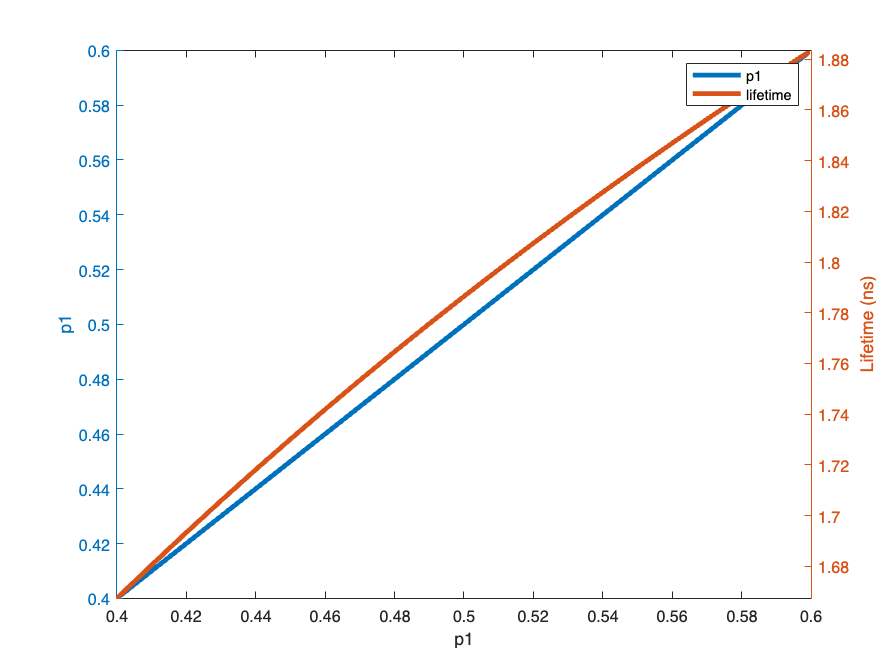

% plot the relationship between p1 and lifetime for double exponential
% decay curve
p1_step = 0.4:0.01:0.6;
p2_step = 1-p1_step;

Lft = zeros(1, length(p1_step));

for i = 1:length(p1_step)

    p1 = p1_step(i);
    p2 = p2_step(i);

    Lft(i) = (tau1*tau1*p1 + tau2*tau2*p2)/(tau1*p1 + tau2*p2);

end

figure
yyaxis left
plot(p1_step, p1_step, 'LineWidth', 3)
ylim([0.4 0.6])
ylabel('p1')
yyaxis right
plot(p1_step, Lft, 'LineWidth', 3)
ylim([min(Lft) max(Lft)])
ylabel('Lifetime (ns)')
legend('p1','lifetime')
xlabel('p1')

function EmpLft = CalcEmpLft(range, n)

x_axis = (1:1:(range(2)-range(1)+1))*(12.5/256);
EmpLft = sum(n(range(1):range(2)).*x_axis)/sum(n(range(1):range(2)));

end



function [p1_fitted, tau_empTrunc, fitting_parameters] = RunFitting(sample_num, n_all)

global spc
ch = 1;

p1_fitted = zeros(sample_num, 1);  % fitted p1
tau_avg = zeros(sample_num, 1); % lifetime calculated based on the fitting curve calculated to infinite
tau_avgTrunc = zeros(sample_num, 1); % lifetime calculated based on the fitting curve within fitting range
tau_empTrunc = zeros(sample_num, 1); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
chi2 = zeros(sample_num, 1); % chi square from fitting
beta6 = zeros(sample_num, 1); % SHG term from fitting
backcorr = zeros(sample_num, 1); % background term from fitting

fitting_parameters = {};

for k = 1:sample_num

    spc.lifetimes{1} = n_all{1}(k,:);

    if length(n_all) > 1

        for i_components = 2:length(n_all)

            spc.lifetimes{1} = spc.lifetimes{1} + n_all{i_components}(k,:);
        end

    end


    % initiate the fitting parameters
            
    spc.fits{1}.beta1 = 10000; % p1 and p2 as 0.5
    spc.fits{1}.beta3 = 10000;
    spc.fits{1}.beta5 = 0; % Delta peak time and SHG are fixed as 0
    spc.fits{1}.beta6 = 0;

    % Running the fitting
    spc_fitexp2prfGY(ch); 

    p1_fitted(k,1)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3); 
    tau_avg(k,1)=spc.fits{ch}.avgTau; 
    tau_avgTrunc(k,1)=spc.fits{ch}.avgTauTrunc;
    tau_empTrunc(k,1)=spc.fits{ch}.EmpTauTrunc;
    chi2(k,1)=spc.fits{ch}.redchisq;
    beta6(k,1)=spc.fits{ch}.beta6;
    backcorr(k,1)=spc.fits{ch}.backCorr;

end

fitting_parameters{1} = tau_avg;
fitting_parameters{2} = tau_avgTrunc;
fitting_parameters{3} = chi2;
fitting_parameters{4} = beta6;
fitting_parameters{5} = backcorr;

end
